% Solve for the coefficients of the CCM.
% We use monochrome and RGB values from 3 patches on a color chart.
% This gives us 3 matrices each with 3 unknowns and 3 equations to solve
% for all 9 coefficients in the CCM.
% Each equation is of the form Sc=b.
diary colorCorrectionLog
S_grayscaleMatrix = [
    80 80 80;
    112 112 112;
    66 66 66;
    ];
% S_grayscaleMatrix = [
%     80 0 0;
%     0 112 0;
%     0 0 66;
%     ];

b_redMatrix = [166 65 51]';
b_greenMatrix = [41 145 58]';
b_blueMatrix = [56 65 144]';

% c_redMatrix = S_grayscaleMatrix\b_redMatrix
% c_greenMatrix = S_grayscaleMatrix\b_greenMatrix
% c_blueMatrix = S_grayscaleMatrix\b_blueMatrix

%transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Show augmented matrix in rref. Visual verification if it is singular.
S_grayscaleMatrix(:,4) = b_redMatrix;
R = rref(S_grayscaleMatrix)

R =      1     1     1     0
     0     0     0     1
     0     0     0     0


% To try to formulate a solution that allows each row of the CCM have
% unique components (a11, a12, a13 are unique instead of identical) we
% eliminate using identical scalar value rows (the patch method) that
% correspond to R1 R2 R3 (different R values of each patch).

% New method has 3 different scalar values map to the same R value in each
% row. This is done by setting an R value (R1=50, etc), and then
% caluclating any scalar value with that R value (online calculator) so the 
% G, B values are arbitrary.

% Therefore, we need 3 grayscale matrices to calculate each row of CCM
% coefficients.
%   [ s11 s12 s13 ]   [ a11 ]     [ R1 ]
%   [ s21 s22 s23 ] * [ a12 ]  =  [ R2 ]
%   [ s31 s32 s33 ]   [ a13 ]     [ R3 ]
                    
S_grayscaleMatrix_red = [
    22 68 120;
    37 65 170;
    67 95 130;
    ];
S_grayscaleMatrix_green = [
    33 71 112;
    63 79 141;
    122 138 159;
    ];
S_grayscaleMatrix_blue = [
    15 94 183;
    20 56 189;
    32 67 111;
    ];

b_redMatrix =   [50 100 200]';
b_greenMatrix = [50 100 200]';
b_blueMatrix =  [50 100 200]';

c_redMatrix = S_grayscaleMatrix_red\b_redMatrix

c_redMatrix =     3.5150
   -0.2765
   -0.0711


% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
c_greenMatrix = S_grayscaleMatrix_green\b_greenMatrix

c_greenMatrix =     1.7219
   -0.0105
   -0.0543


c_blueMatrix = S_grayscaleMatrix_blue\b_blueMatrix

c_blueMatrix =     7.5602
   -0.3475
   -0.1679


initial_rgbImage = 976×1296×3 uint8 array
initial_rgbImage(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

colorCorrectionMatrix =     3.5150   -0.2765   -0.0711
    1.7219   -0.0105   -0.0543
    7.5602   -0.3475   -0.1679


test_ccm =      1     0     0
     0     1     0
     0     0     1


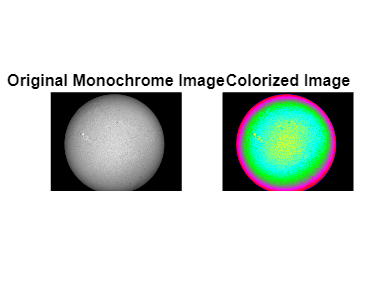

dt = datetime
   10-Jan-2025 18:13:51


filename = "colorized_images/colorized_image_20250110181357.png"

returned_img = 976×1296×3 uint8 array
returned_img(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


returned_img = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Test if tinting the image is possible.
% b_redMatrix = [200 + zeros(1, 8)]'
% b_greenMatrix = [50 + zeros(1, 8)]'
% b_blueMatrix = [200 + zeros(1, 8)]'
% 
% c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)
% c_greenMatrix = lsqr(S_grayscaleMatrix, b_greenMatrix)
% c_blueMatrix = lsqr(S_grayscaleMatrix, b_blueMatrix)

% transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

function rgb_prime = interpolation_map(scalar)
    % Store corresponding lists of grayscale values and rgb vectors.
    grayscale_list = [0 29 76 105 150 179 226 255]; % 0 and 255 are needed as lower/upper bounds.
    rgb_list = [
          0   0   0;    % black
          0   0 255;    % blue
        255   0   0;    % red
        255   0 255;    % magenta
          0 255   0;    % green
          0 255 255;    % cyan
        255 255   0;    % yellow
        255 255 255;    % white
    ];
    % For scalar, find closest stored grayscale values, average between the
    % rgb values in each corresponding vector.
    % if scalar in grayscale_list:
    if ismember(scalar, grayscale_list)
        % get index of grayscale_list
        index = find(grayscale_list == scalar);
        % get rgb_list(index)
        rgb_prime = [rgb_list(index, :)]';
        return
    else
        % get index of first grayscale_list item greater than scalar
        index = find(grayscale_list > scalar, 1, 'first');
        % get value of grayscale_list item at that index and previous index
        gray_ceiling = grayscale_list(index);
        gray_floor = grayscale_list(index-1);
        % get weight:
            % ( scalar - grayscale_list(index-1) ) /
            % ( grayscale_list(index) - grayscale_list(index-1) )
        gray_weight = (scalar - gray_floor) / (gray_ceiling - gray_floor);
            
        % r_temp = (rgb_list(index)[1] - rgb_list(index-1)[1]) * weight
        % ...
        r_temp = (rgb_list(index, 1) - rgb_list(index-1, 1)) * gray_weight;
        g_temp = (rgb_list(index, 2) - rgb_list(index-1, 2)) * gray_weight;
        b_temp = (rgb_list(index, 3) - rgb_list(index-1, 3)) * gray_weight;
        % r_prime = r_temp + rgb_list(index-1)[1]
        % ...
        r_prime = r_temp + rgb_list(index-1, 1);
        g_prime = g_temp + rgb_list(index-1, 2);
        b_prime = b_temp + rgb_list(index-1, 3);

       rgb_prime = [r_prime g_prime b_prime]';
       return
    end
end

function rgbImage = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)
    % Read the monochrome image.
    initial_rgbImage = imread('images/march26-fullDisk4.png', 'png')
    grayImage = rgb2gray(initial_rgbImage);
    
    % Define a color correction matrix for RGB color mapping.
    % Simple example below.
    colorCorrectionMatrix = [
        c_redMatrix'; % Red channel mapping
        c_greenMatrix'; % Green channel mapping
        c_blueMatrix'; % Blue channel mapping
        ]

    % test.
    % test_ccm = [
    %     0.9 0.05 0.05;
    %     0.05 0.9 0.05;
    %     0.05 0.05 0.9;]
    test_ccm = [
        1 0 0;
        0 1 0;
        0 0 1;]
    
    % Get image dimensions.
    [rows, cols] = size(grayImage);
    
    % Initialize RGB image matrix.
    % rgbImage = zeros(rows, cols, 3);
    rgbImage = initial_rgbImage; % Hijacks format used by imread.
    
    % Apply color correction by looping over each pixel.
    for i = 1:rows
        for j = 1:cols
            % Get grayscale value of current pixel.
            grayValue = double(grayImage(i, j)); 
    
            % Apply color correction matrix to map grayscale value to RGB
            % values.
            rgb_prime_vec = interpolation_map(grayValue);
            % rgbValue = colorCorrectionMatrix * rgb_prime_vec;
            rgbValue = test_ccm * rgb_prime_vec;
            % Store RBG values in the output image matrix.
            rgbImage(i, j, :) = uint8(rgbValue); % ':' is the rgb vector
        end
    end
    
    % Display the original monochrome image and the transformed color image.
    figure;
    subplot(1, 2, 1);
    imshow(grayImage);
    title('Original Monochrome Image');
    % rgbImage
    
    subplot(1, 2, 2);
    imshow(rgbImage);
    title('Colorized Image');
    
    % Save the colorized image to a new file.
    dt = datetime("now")
    dt.Format = 'yyyyMMddHHmmSS';
    filename = 'colorized_images/colorized_image_' + string(dt) + '.png'
    imwrite(rgbImage, filename);

    % grayscale_list = [-10 29 76 105 150 179 226 245];
    % for grayValue = grayscale_list
    %     rgb_prime_vec = interpolation_map(grayValue+10);
    %     rgbValue = test_ccm * rgb_prime_vec;
    %     fprintf('Gray Value: %d\n', grayValue);
    %     fprintf('RGB Prime Vector:    [%.2f, %.2f, %.2f]\n', rgb_prime_vec);
    %     fprintf('Corrected RGB Value: [%.2f, %.2f, %.2f]\n', rgbValue);
    % end
end